## nirs.modules.DiscardStims

This module can discard the specific stims. 

**Example Usage: **

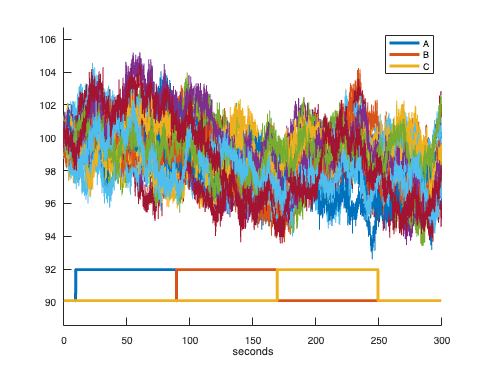

raw = nirs.testing.simData([], @(t)nirs.testing.blockedStimDesign(t,80,0,3));
raw.draw

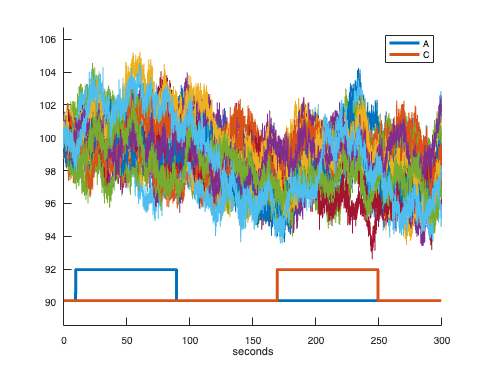


job = nirs.modules.DiscardStims();
job.listOfStims = {'B'}; %Remove stim condition 'B'
raw = job.run(raw);
figure; raw.draw